data = readmatrix('flightData.dat');
format long g
disp(data(1:750,:))

                         0                         0                         0
                         1                        12         0.224887556221889
                         2                        24         0.449775112443778
                         3                        36         0.674662668665667
                         4                        48         0.899550224887556
                         5                        60          1.12443778110945
                         6                        72          1.34932533733133
                         7                        84          1.57421289355322
                         8                        96          1.79910044977511
                         9                       108            2.023988005997
                        10                       120          2.24887556221889
                        11                       132          2.47376311844078
                        12                       144

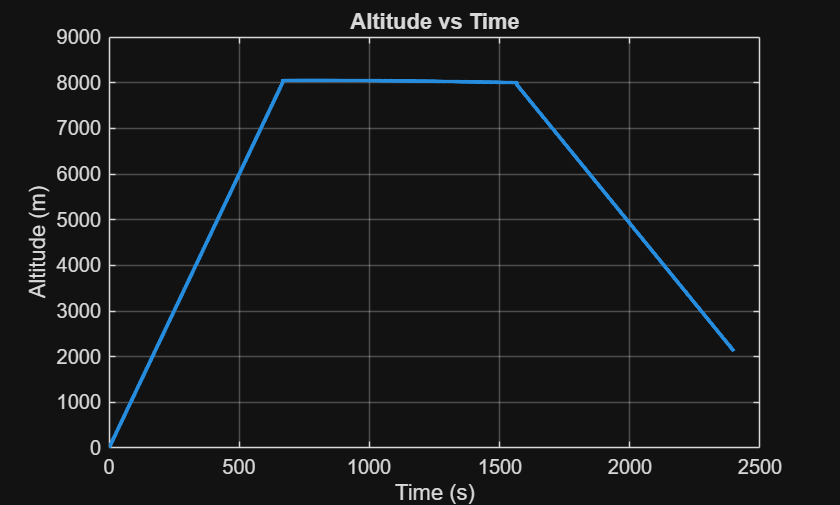


t       = data(:,1);
alt     = data(:,2);
speed   = data(:,3);

ALT_LOW = 300;       % below this = near ground
CLIMB_RATE = 3;      % >3 m/s = climbing
DESCENT_RATE = -3;   % <-3 m/s = descending
SPEED_TAKEOFF = 40;  % >40 m/s = airborne

phase = strings(length(t),1);

alt_rate = [0; diff(alt)];
CRUISE_RATE = 2;   % |alt_rate| <= 2 m/s = cruise


for i = 1:length(t)

    if alt(i) < ALT_LOW && speed(i) < 40
        phase(i) = "ground";

    elseif alt(i) < ALT_LOW && speed(i) >= 40
        phase(i) = "takeoff";

    elseif alt_rate(i) > CLIMB_RATE
        phase(i) = "climb";

    elseif abs(alt_rate(i)) <= CRUISE_RATE
        phase(i) = "cruise";

    elseif alt_rate(i) < DESCENT_RATE
        phase(i) = "descent";
    else
        phase(i) = "landing";
    end


end


% ============================
%  Altitude vs Time
% ============================
figure;
plot(t, alt, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Altitude (m)');
title('Altitude vs Time');
grid on;

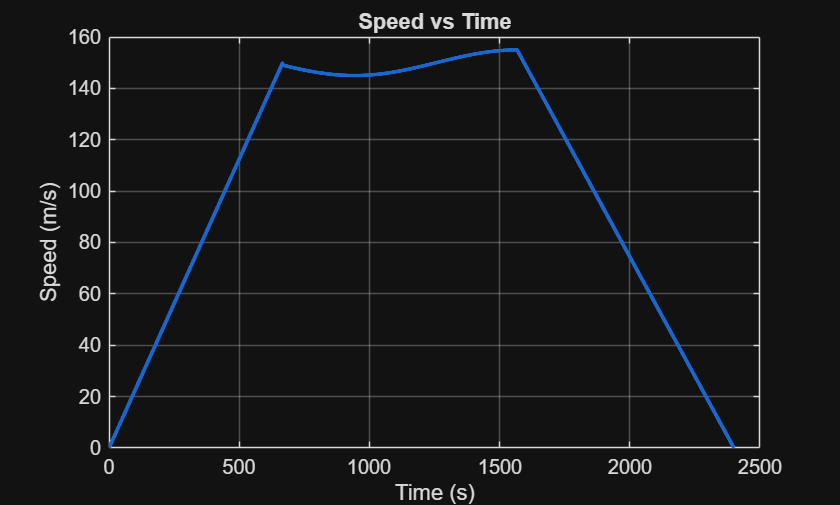


% ============================
%  Speed vs Time
% ============================
figure;
plot(t, speed, 'LineWidth', 2, 'Color', [0.1 0.4 0.8]);
xlabel('Time (s)');
ylabel('Speed (m/s)');
title('Speed vs Time');
grid on;

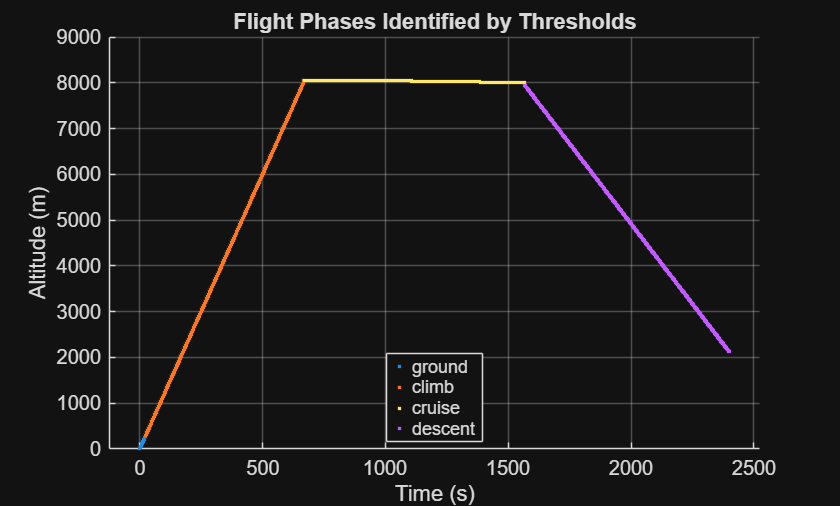


% ============================
%  Phase-Colored Plot
% ============================
figure;
gscatter(t, alt, phase);
xlabel('Time (s)');
ylabel('Altitude (m)');
title('Flight Phases Identified by Thresholds');
grid on;

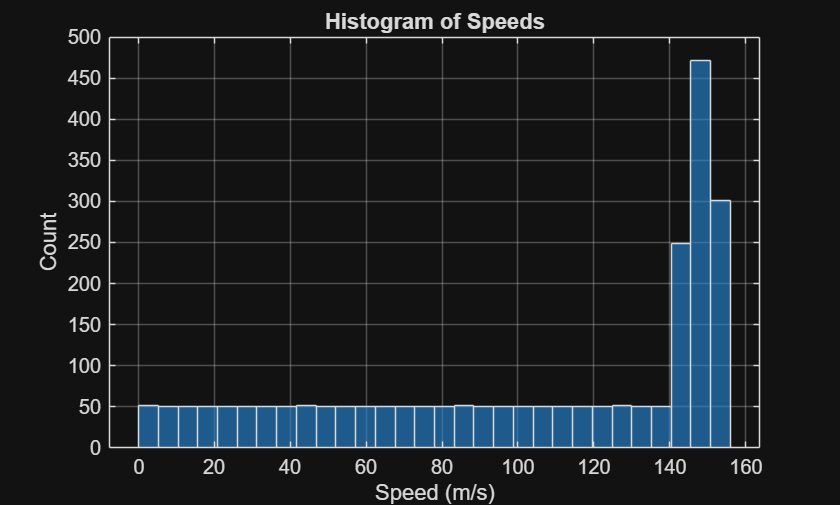


% ============================
%  Histogram of Speeds
% ============================
figure;
histogram(speed, 30);
xlabel('Speed (m/s)');
ylabel('Count');
title('Histogram of Speeds');
grid on;



% --- Compute altitude rate ---
alt_rate = [0; diff(alt)];

% --- Max climb rate ---
max_climb_rate = max(alt_rate(phase == "climb"));

% --- Average cruise speed ---
avg_cruise_speed = mean(speed(phase == "cruise"));

% --- Descent duration ---
descent_idx = find(phase == "descent");
descent_duration_sec = t(descent_idx(end)) - t(descent_idx(1));
descent_duration_min = descent_duration_sec / 60;

% --- Display results ---
fprintf("Max climb rate: %.2f m/s\n", max_climb_rate);

Max climb rate: 44.63 m/s


fprintf("Average cruise speed: %.2f m/s\n", avg_cruise_speed);

Average cruise speed: 148.88 m/s


fprintf("Descent duration: %.2f sec (%.2f min)\n", ...
        descent_duration_sec, descent_duration_min);

Descent duration: 833.00 sec (13.88 min)
